# DEMO DCT

In questa demo applichiamo diverse trasformate frequenziali bi-dimensionali alle immagini, e ne osserviamo la capacità di riconoscere *features* e l'effetto "sparsificante"

## Iniziamo!

Carichiamo e mostriamo una delle immagini disponibili. Il formato PGM (portable grayscale map) è un semplice formato non compresso per le immagini a livelli di grigio. 

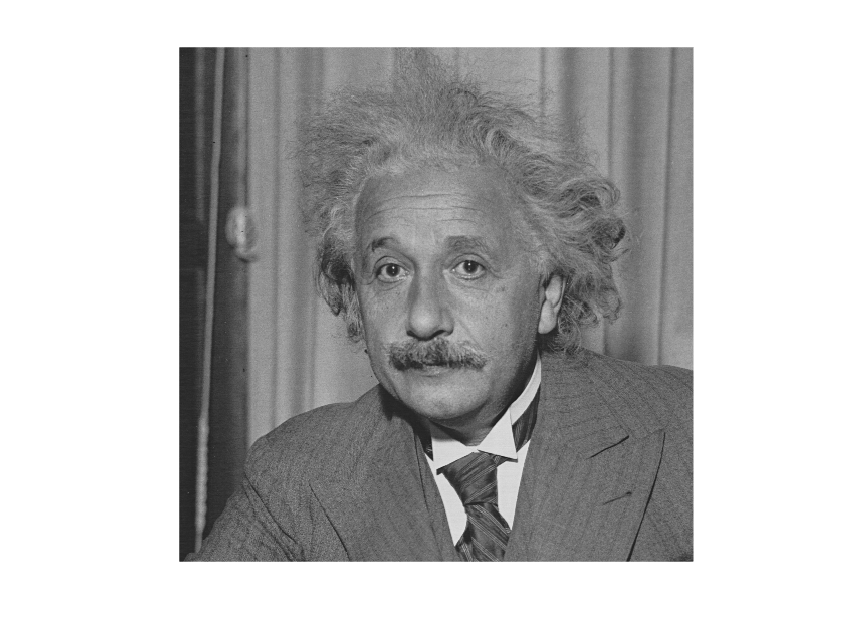

close all; clear variables; 
imageName = "einst";
fileName = sprintf('%s.pgm',imageName);
x= double(imread(fileName));
image(x); colormap(gray); axis image; axis off; 

## Full-frame DFT 

Calcoliamo la trasformata di Fourier discreta 2D di un'immagine. Questa è chiamata trasformata "full-frame", in opposizione alla trasformata "block-based", in cui l'immagine è divisa in blocchi e la trasformata è calcolata blocco per blocco.

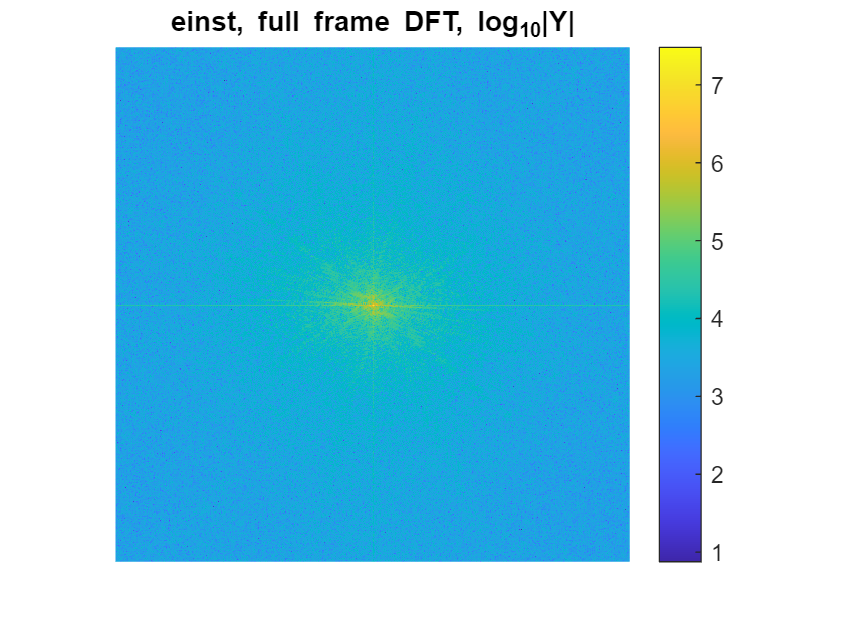

DFT = fft2(x); % Calcolare la DFT 2D utilizzando l'algoritmo della FFT
centredSpectrum = fftshift(DFT); % Mettere la frequenza (0,0) al centro dell'immagine
figure; imagesc(log10(1+abs(centredSpectrum))); % Visualizzare lo spettro
axis image; colorbar; axis off % Visualizzazione migliorata
title(sprintf('%s, full frame DFT, log_{10}|Y|',imageName));

La DFT 2D è l'analogo bidimensionale e discreto della ben nota trasformata di Fourier. Si tratta quindi di una trasformata lineare invertibile e ortogonale. Può essere vista come una rotazione nello spazio euclideo ${\mathbb{R}}^N$ ($N$ è il numero totale di pixel nell'immagine). Essa si può applicare ad un immagine a livelli di grigio, oppure ad ogni singolo canale di un'immagine a colori. In questa demo, per semplicità, considereremo solo immagini a livelli di grigio. 

La DFT 2D produce un insieme di coefficienti di Fourier (numeri complessi) della stessa dimensione dell'immagine originale. Per facilitare la visualizzazione si considera solo il modulo e si usa il comando `fftshift` che scambia le posizioni dei quattro quadranti dell'immagine, in modo che il coefficiente a frequenza zero sia collocato al centro dell'immagine, mentre le alte frequenze siano vicine ai bordi. Nelle parti superiore e inferiore dell'immagine trasformata si trovano le alte frequenze verticali; nelle parti più a sinistra e più a destra dell'immagine si trovano le alte frequenze orizzontali.

I coefficienti trasformati sono visualizzati in scala logaritmica per facilitare la visualizzazione visto che essi hanno ordini di grandezza molto diversi. Più precisamente si visualizza $\log_{10} \left(1+|\textrm{DFT}|\right)$: infatti la funzione $\log_{10} \left(1+x\right)$ è una corrispondenza tra $\mathbb{R}{\;}^+$ e  $\mathbb{R}{\;}^+$ con crescita "lenta", permettendo quindi di visualizzare correttamente sia valori molto grandi, sia valori molto piccoli. 

Tutte le immagini *naturali* (cioè foto, per opposizione ad altri tipi d'immagine ottenute con altri tipi di sensore) mostrano una concentrazione di coefficienti "grandi" (cioè il cui modulo è grande) in prossimità della frequenza nulla: le immagini naturali sono infatti segnali "passa-basso". La maggior parte delle immagini mostra anche una "croce": due linee ortogonali che passano per il centro dell'immagine. Si tratta di *artefatti* legati ad alcune proprietà della DFT. Le immagini con "direzioni dominanti" (cioè contorni con direzioni parallele) mostrano dei "raggi" nella trasformata di Fourier, orientati ortogonalmente alla direzione del contorno. Infine, alcune immagini mostrano "impulsi" nel dominio della frequenza, che corrispondono a modelli periodici nel dominio spaziale (ad esempio, il modello periodico del tessuto, della stoffa, ...).

In Matlab, la 2D-DFT viene calcolata con un algoritmo di Fast Fourier Transform (`fft2`).

**Generate la DFT delle varie immagini del dataset e provate a riconoscere le features della DFT. **

## Istogramma dell'ampiezza dei coeff. DFT

Come discusso in classe, l'obiettivo principale delle trasformate nel contesto della compressione è quello di "sparsificare" il segnale. Il segnale originale (l'immagine) non è sparso: tutti i livelli di grigio possono comparire e, anche se in una singola immagine si notano dei "picchi" nell'istogramma, se si prende un insieme sufficientemente ampio di immagini, l'istogramma globale tende a essere piatto.

Dopo una trasformazione di frequenza, il segnale viene sparsificato. Ossia, si osservano pochi coefficienti grandi (a bassa frequenza) e molti coefficienti piccoli (ad alta frequenza). Ciò è visibile anche nell'istogramma della trasformata di Fourier. 

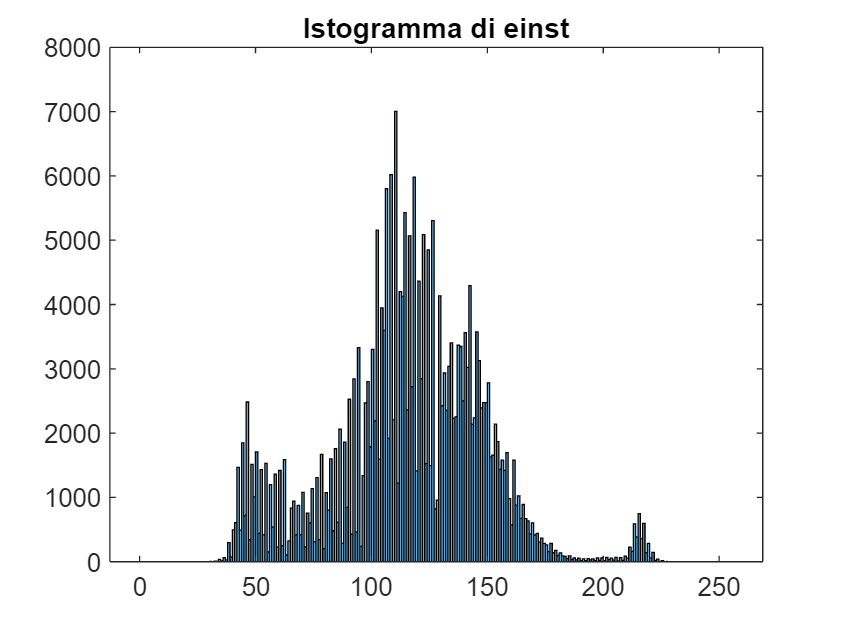

% Compute and show the image histogram
histogram(x(:),0:256); title(sprintf('Istogramma di %s',imageName) );

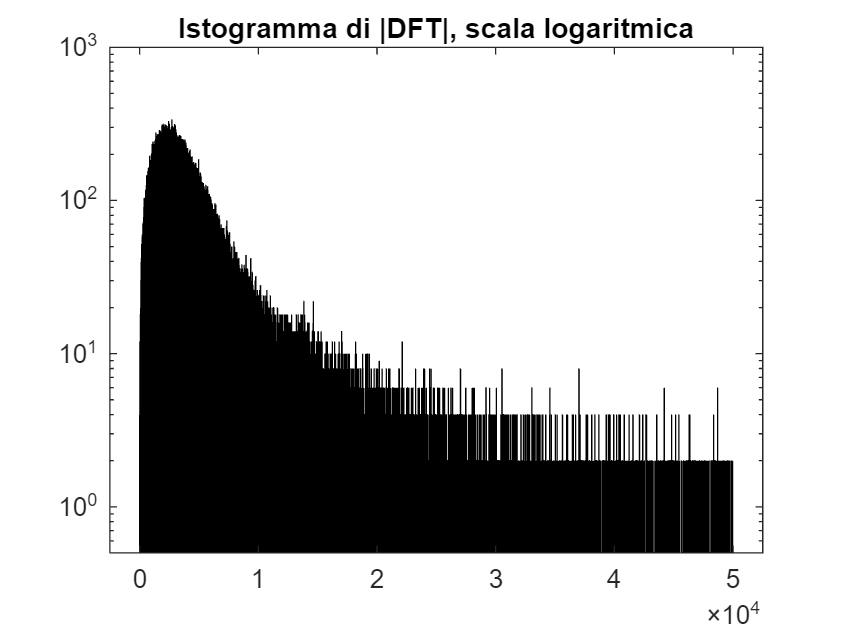

nBins = 1e4;
bins = linspace(0,5e4,nBins);
histogram(abs(DFT),bins); set(gca,'YScale', 'Log'); ylim([0.5 gca().YLim(2)]);
title('Istogramma di |DFT|, scala logaritmica');

## Trasformata coseno discreta (DCT)

La Trasformata coseno discreta (*Discrete Cosine Transform*, DCT) è una variante della DFT. Ha una migliore sparsificazione e produce coefficienti a valori reali e a frequenze unicamente positive. 

Calcoliamo e visualizziamo la DCT bidimensionale "full-frame" utilizzando il comando `dct2`. Tracciamo poi l'istogramma. 

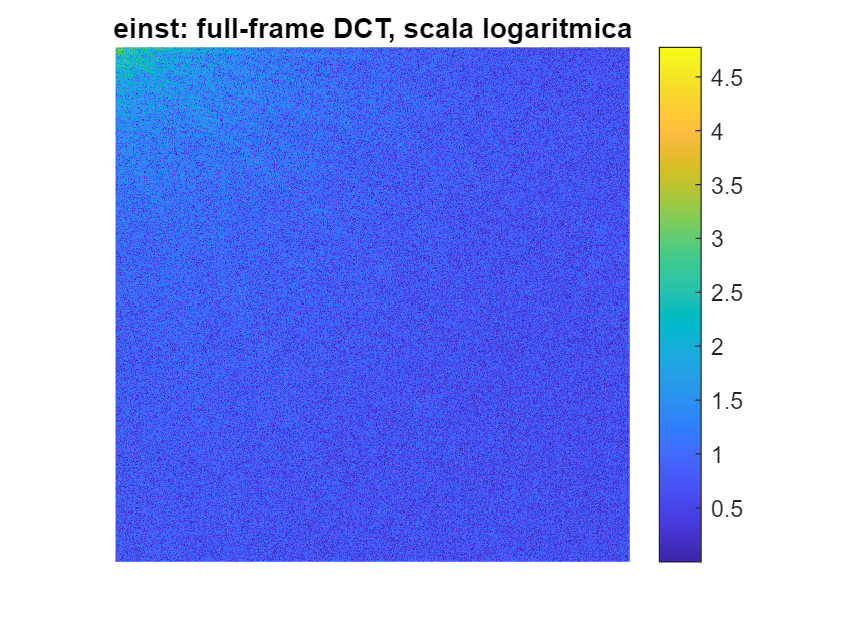

DCT = dct2(x);
imagesc(log10(abs(DCT)+1)); axis image; colorbar; axis off
title(sprintf('%s: full-frame DCT, scala logaritmica',imageName) );

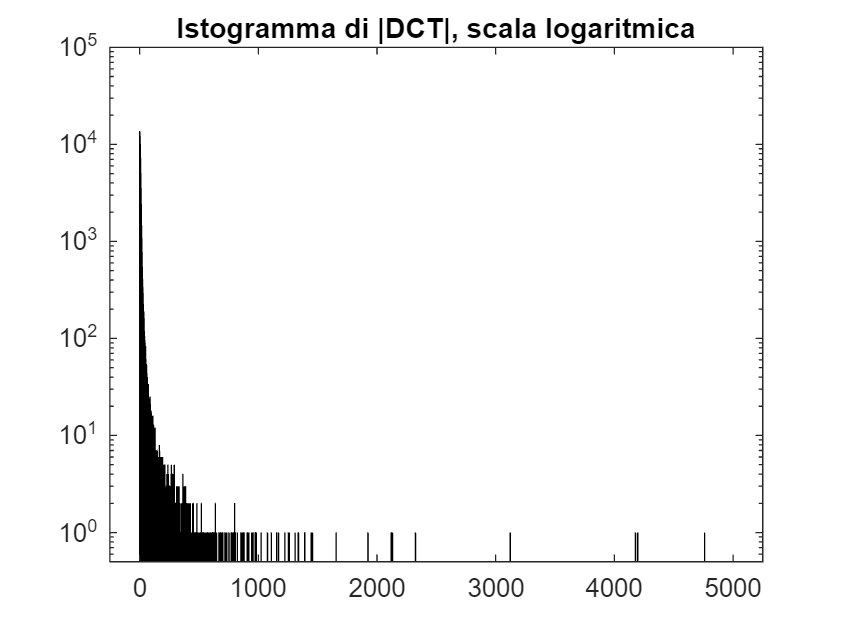

nBins = 1e4;
bins = linspace(0,5e3,nBins); % Intervalli dell'istogramma definiti manualmente
% Log-scale histogram
histogram(abs(DCT),bins);
set(gca,'YScale', 'Log'); ylim([0.5 gca().YLim(2)]);
title('Istogramma di |DCT|, scala logaritmica');

La DCT ha il coefficiente a frequenza zero **in alto a sinistra**, mentre la frequenza aumenta andando verso destra e verso il basso. In genere presenta caratteristiche simili alla DFT, ma l'effetto "croce" (ora visibile nelle righe superiori e nelle colonne di sinistra) è più debole. I coefficienti di modulo grande sono più concentrati nella regione a bassa frequenza (angolo in alto a sinistra). 

**Nel confrontare gli istogrammi della DFT e della DCT, si osservino bene i valori sugli assi: le ascisse danno il valore del coefficiente della trasformata, le ordinate ne danno il numero di occorrenze**

## Trasformata in blocchi

Le immagini non sono segnali stazionari. Esse sono costituite da aree molto stazionarie (l'"interno" dell'oggetto) separate da transizioni nette (contorni). Pertanto, un'analisi *locale* del segnale ha senso. 

L'immagine è divisa in blocchi di dimensione $n\times n$, where $n\in {\left\lbrace 2^k \right\rbrace }_{k\in \left\lbrace 1,2,\ldotp \ldotp \ldotp ,8\right\rbrace }$. In altre parole, i blocchi hanno dimensione $2\times 2$,  $4\times 4$,  $8\times 8$, ... , fino a $64\times 64$. 

Quindi, si calcola una 2D-DCT per ogni blocco e infine si visualizzano i blocchi trasformati e l'istogramma cumulativo.  

Si noti il modo in cui viene implementata la DCT a blocchi. Sfruttiamo la funzione `blockproc` di Matlab, che applica una funzione a tutti i blocchi di un'immagine. Come input riceve l'immagine, la dimensione dei blocchi e un "handler", cioè un puntatore a una funzione. L'handler è opportunamente definito con una sintassi specifica di Matlab:

"`handler = @(input) <calcolo dell'output>`" nella riga 30. 

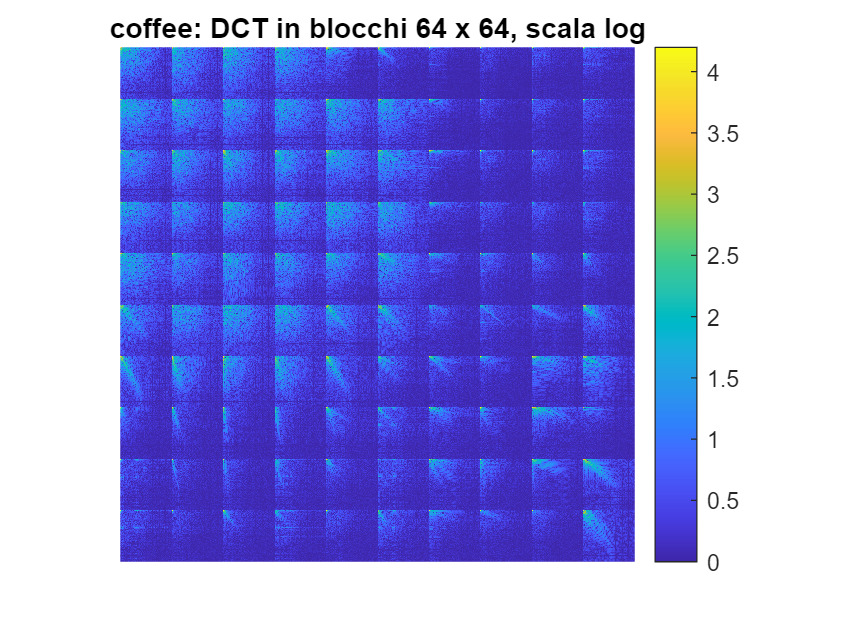

log2blockSize = 6; % cioè il parametro k nel testo qui sopra
blockSize = 2^log2blockSize;  % l'abbiamo chiamato n nel testo qui sopra
dctfun = @(block_struct) dct2(block_struct.data);
blkDCT = blockproc(x, [blockSize blockSize], dctfun);
imagesc(log10(abs(blkDCT)+1)); colorbar ; 
title(sprintf('%s: DCT in blocchi %d x %d, scala log',...
    imageName, blockSize,blockSize)); 
axis image; axis off; 

**Cambiate la dimensione dei blocchi e l'immagine, ed osservate il risultato: come varia la distribuzione spaziale delle features nell'immagine trasformata? **

Mostriamo anche in questo caso l'istogramma dei coefficienti della trasformata. 

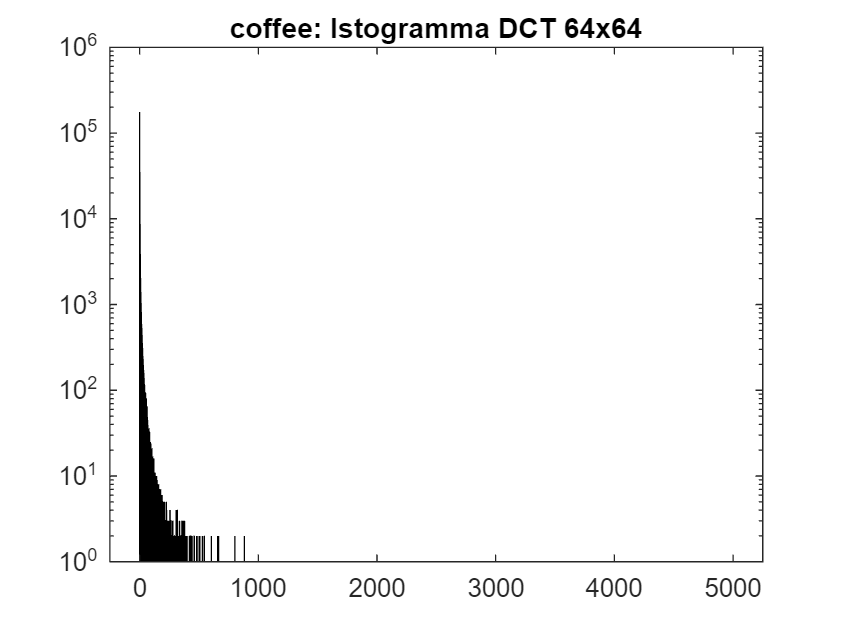

nBins = 1e4;
bins = linspace(0,5e3,nBins); % Intervalli dell'istogramma definiti manualmente
histogram(abs(blkDCT),bins);
set(gca,'YScale', 'Log')
title(sprintf('%s: Istogramma DCT %dx%d',imageName, blockSize,blockSize));

**Osservare come varia l'istogramma (la sparsità) al variare della dimensione dei blocchi**

## OPZIONALE: Il guadagno di codifica. 

Il guadagno di codifica (coding gain) è una misura quantitativa del potere sparsificante di una trasformata in blocchi. Si calcola la trasformata per ognuno degli $M$ blocchi in cui è divisa un'immagine. All'interno di ogni blocco ci aspettiamo pochi coefficienti grandi (quelli in alto a sinistra, le basse frequenze) e molti piccoli (tutti gli altri). Per misurare questo fenomeno, prima calcoliamo la varianza di ogni coefficiente frequenziale (detto anche *sottobanda*), prendendone i valori che appaiono nei diversi blocchi. Una sottobanda "ricca d'informazione" avrà una varianza grande. Una sottobanda scarsamente informativa avrà una varianza piccola (tutte le volte appaiono valori vicini tra loro e tipicamente prossimi a zero). Se un segnale non è sparso, tutte le varianze avranno valori vicini, perché tutti i campioni hanno la stessa importanza. Ciò accade se ad esempio, come "trasformata" si considera l'identità. In altre parole il segnale non trasformato non è sparso. Se il segnale è sparso, alcune varianze saranno grandi, altre saranno piccole, perché alcune sottobande sono informative, ma molte altre sono trascurabili. Nel primo caso (segnale non sparso), la **media geometrica **delle varianze sara vicina al valore massimo possibile, che è uguale alla **media aritmetica **delle varianze e che non dipende dalla trasformata (per la proprietà di orgogonalità). Nel secondo caso invece (segnale sparso), la media geometrica delle varianze sarà piccola. Si definisce *guadagno di codifica *il rapporto tra media aritmetica e media geometrica delle varianze: più è grande tale valore, più la trasformata ha potere sparsificante. 


$$\textrm{CG}=\frac{\sigma_{\textrm{AM}}^2 }{\sigma_{\textrm{GM}}^2 }\;\;$$
       
$${\textrm{CG}}_{\textrm{dB}} =10\;\log_{10}$$

$$\frac{\sigma_{\textrm{AM}}^2 }{\sigma_{\textrm{GM}}^2 }$$


La teoria della quantizzazione per blocchi mostra che il coding gain corrisponde al rapporto tra la distorsione che si ottiene quantizzando direttamente i valori del blocco di pixel (con un quantizzatore ottimizzato) e la distorsione che si ottiene applicando prima la trasformata e poi la quantizzazione (ancora con un quantizzatore ottimizzato). Quindi il CG ci dice di quanto miglioriamo la qualità della codifica applicando una trasformata rispetto al caso in cui quantizziamo direttamente i campioni del segnale. 

Calcoliamo ora il guadagno di codifica. 

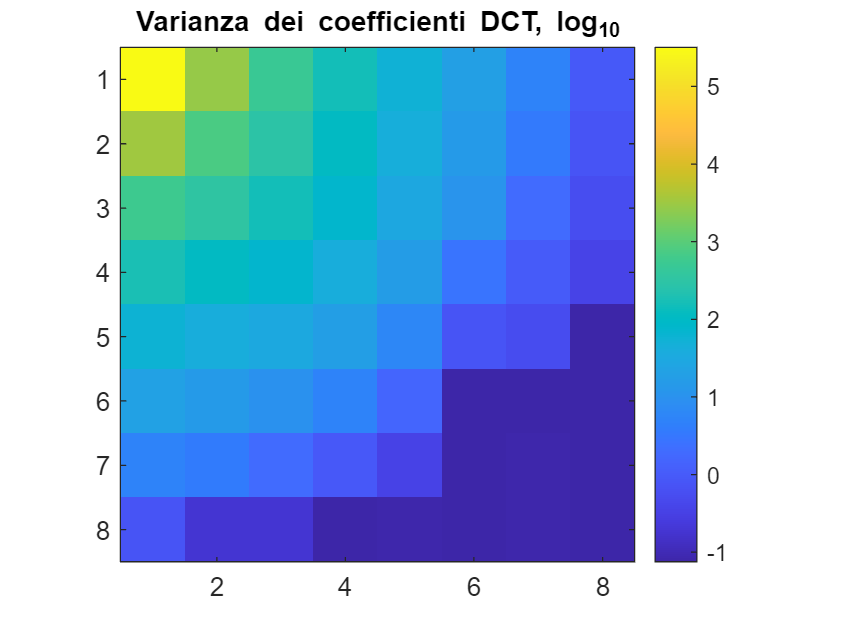

imageName = "coffee";
fileName = sprintf('%s.pgm',imageName);
x= double(imread(fileName));
[rows, cols] = size(x); 
log2blockSize = 3;
blockSize = 2^log2blockSize; 
dctfun = @(block_struct) dct2(block_struct.data);
blkDCT = blockproc(x, [blockSize blockSize], dctfun);
numBlocks = rows*cols/ blockSize / blockSize; 
cuboid = zeros(blockSize, blockSize, numBlocks); % Una matrice 3D con valori tutti nulli
blockIndex=0;
for r = 0:blockSize:rows-1      
    for c = 0:blockSize:cols-1
        blockIndex=blockIndex+1;
        block = blkDCT(r+1:r+blockSize, c+1:c+blockSize); %Prendere il blocco n-esimo
        cuboid(:,:,blockIndex) = block; %...e inserirlo nell'n-esimo canale della matrice 3D
    end
end
vars =zeros(blockSize);
for i=1:blockSize
    for j = 1:blockSize
        tmp = cuboid(i,j,:); %prendere tutti i coeff. alla stessa freq. i,j
        vars(i,j) = var(tmp(:)); %calcolare la varianza della sottobanda
    end
end
imagesc(log10(vars)); colorbar; axis image; 
title('Varianza dei coefficienti DCT, log_{10}');

codingGain = mean2(vars) / exp(mean2(log(vars)));
CG_dB = 10*log10(codingGain);
fprintf('%s, DCT %.dx%.d. Coding gain: %4.2f dB\n',imageName, blockSize,blockSize, CG_dB);

coffee, DCT 8x8. Coding gain: 29.35 dB


**Osservare come varia il CG al variare della dimensione dei blocchi. **